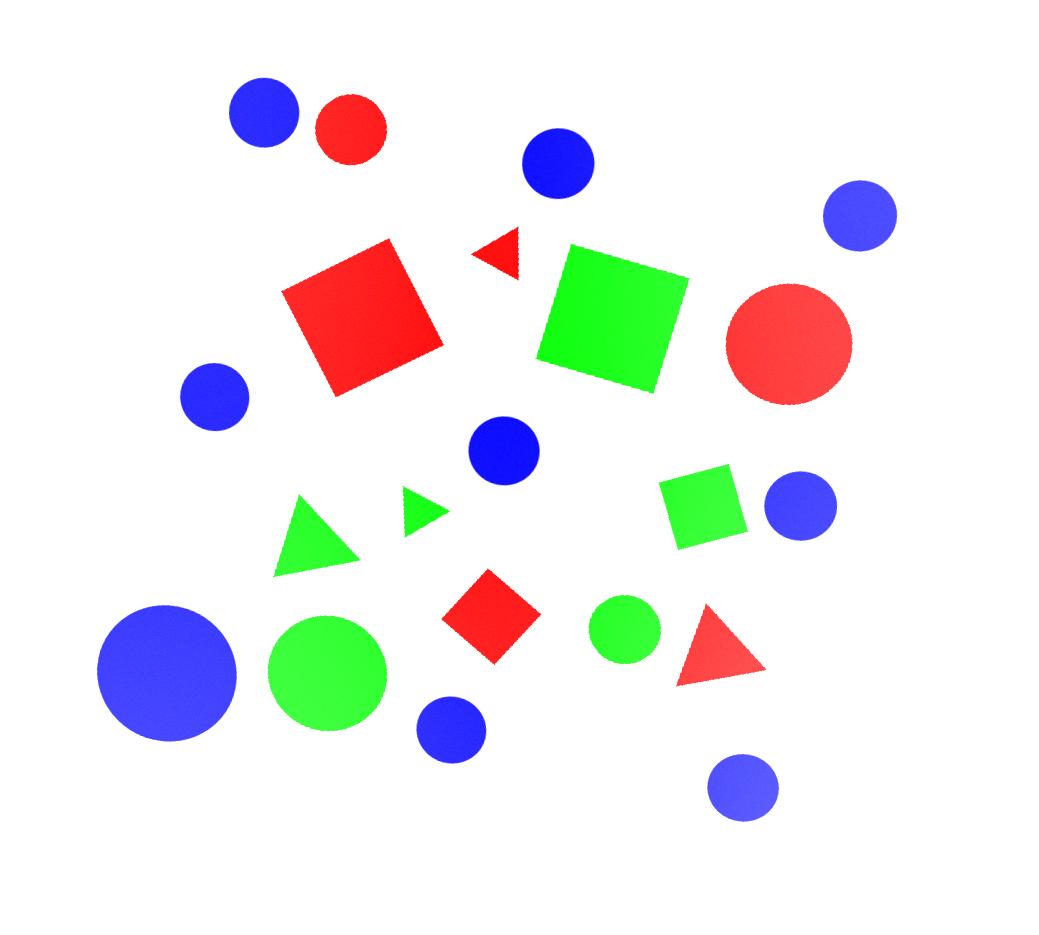

clear All; close all; clc;

img = imread("test_images/test_34.png");
imshow(img);

## Version 3

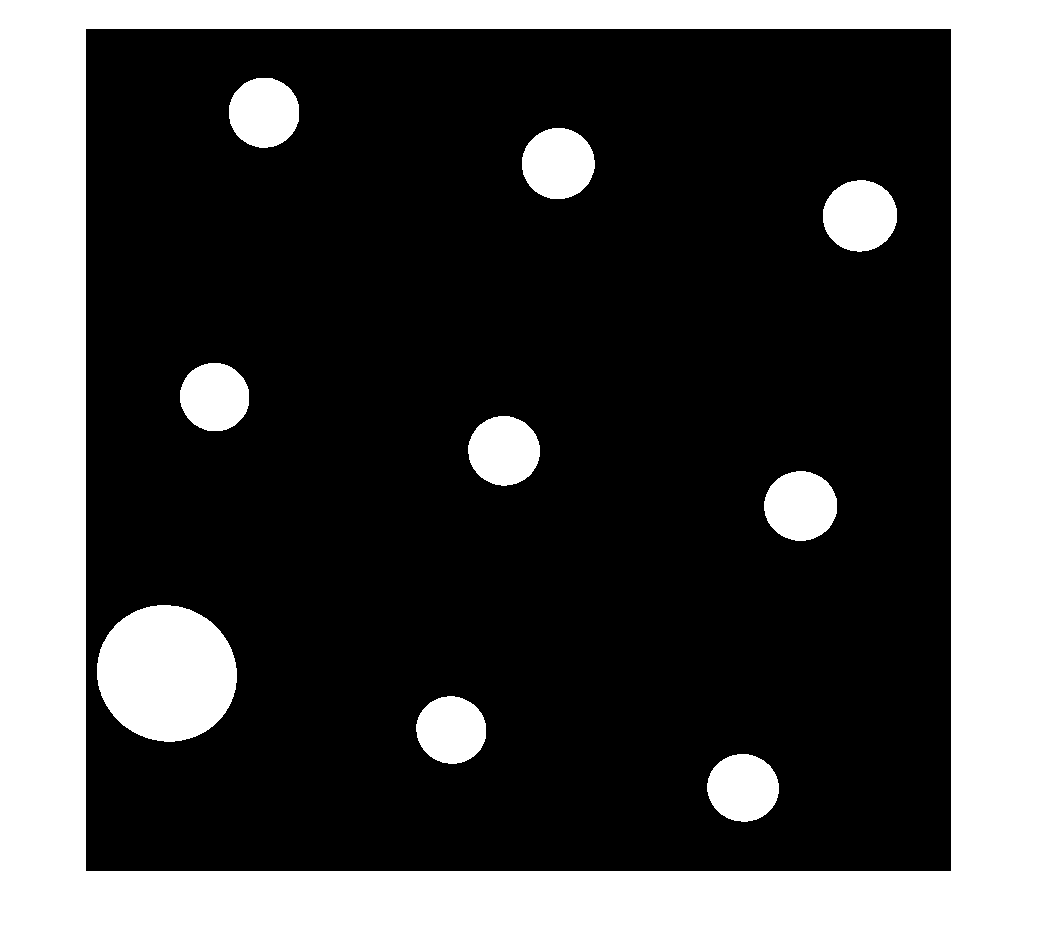

% Representative cases 34 38 43
blue = (img(:,:,3) > 100 & img(:,:,1) < 10 & img(:,:,2) < 10) | (img(:,:,3) == 255 & img(:,:,2) < 200 & img(:,:,1) < 200); % image 43 and 34
% % figure(); imshow(blue); title('ohyeah');

blueClean = medfilt2(blue, [5,5]);
stats = regionprops("table", blueClean, "Centroid");

% Store data
centroids = cat(1,stats.Centroid);
binary_img = blueClean;

imshow(binary_img);

## Version 2


grayVal = [220 0 0];

chromaImg = chromadapt(img,grayVal);
imshow(chromaImg);

gray = 255 - rgb2gray(img);
imshow(gray);

blue = img(:,:,3);

red = img(:,:,1); 
redBin = imbinarize(red,"adaptive", "Sensitivity", 0.8); figure(); imshow(redBin); title('redBin');
green = img(:,:,2); 
greenBin = imbinarize(green,"adaptive", "Sensitivity", 0.8); figure(); imshow(greenBin); title('greenBin');

% blue = blue > 115 & red < 20 & green < 20;
% imshow(blue);

% test gray minus green and red
grayMinus = gray - uint8(redBin)*255 - uint8(greenBin)*255;
imshow(grayMinus);
% grayBin = imbinarize(grayMinus, 'adaptive', 'Sensitivity', 0.55);
grayBin = imbinarize(grayMinus, 30/255);
imshow(grayBin);

blueClean = medfilt2(grayBin, [10,10]);
imshow(blueClean);

% Get props' centroids
stats = regionprops("table", blueClean, "Centroid");
% Store data
centroids = cat(1,stats.Centroid);
binary_img = blueClean;

% Solution
[bw, centroids] = segment_blue_markers(img);


## Version 1


% % Get hue value
% [H,S,V] = rgb2hsv(img);
% % Examine the image and binarize blue area
% blue = H>0.65 & H<0.68;
% % imshow(H);
% % imshow(S);
% % imshow(V);
% 
% % Clean noise
% blueClean = medfilt2(blue, [5,5]);
% 
% % Get props' centroids
% stats = regionprops("table",blueClean,"Centroid");
% % Store data
% centroids = cat(1,stats.Centroid);
% binary_img = blueClean;
% 
% % Solution
% [bw, centroids] = segment_blue_markers(img);




